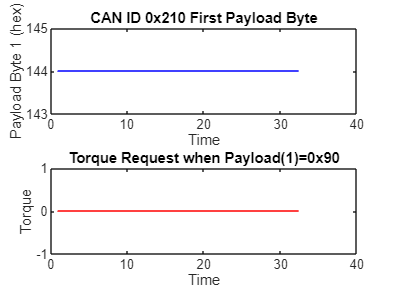

% Read CSV as text to preserve hex values
opts = detectImportOptions('Standard_Setup_1.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('Standard_Setup_1.csv', opts);

% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time  = str2double(rawData{:,1});             % timestamp
canID = hex2dec(rawData{:,3});                % CAN ID in decimal
payloadByte1 = hex2dec(rawData{:,6});         % first payload byte
lsbByte      = hex2dec(rawData{:,7});         % second payload byte
msbByte      = hex2dec(rawData{:,8});         % third payload byte

% Filter ID = 0x210
idx210 = (canID == hex2dec('210'));
time210 = time(idx210);
payload210 = payloadByte1(idx210);
lsb210     = lsbByte(idx210);
msb210     = msbByte(idx210);

% Filter torque messages (first payload byte = 0x90)
idxTorque = (payload210 == hex2dec('90'));
timeTorque = time210(idxTorque);

msb = lsb210(idxTorque);
lsb = msb210(idxTorque);

% Combine little-endian 16-bit
torque16u = bitor(uint16(lsb), bitshift(uint16(msb),8));

% Interpret as signed int16
torque16 = typecast(torque16u, 'int16');

% --- Plot ---
figure;

subplot(2,1,1);
plot(time210, payload210, 'b');
xlabel('Time');
ylabel('Payload Byte 1 (hex)');
title('CAN ID 0x210 First Payload Byte');

subplot(2,1,2);
plot(timeTorque, double(torque16), 'r');
xlabel('Time');
ylabel('Torque');
title('Torque Request when Payload(1)=0x90');